mea_max = measure_white(ol,cs);

Yxy =    52.6840    0.3789    0.4096



mea_min = measure_black(ol,cs);

Yxy =     0.0313    0.4063    0.4138


load('runme_data','M','B')

d65 = B;

spd_target_orig = d65;

% spd_0 = ls.spd_0';
% spd_max = ls.spd_all' - spd_0;
mea_max = measure_white(ol,cs);

Yxy =    52.2940    0.3791    0.4097


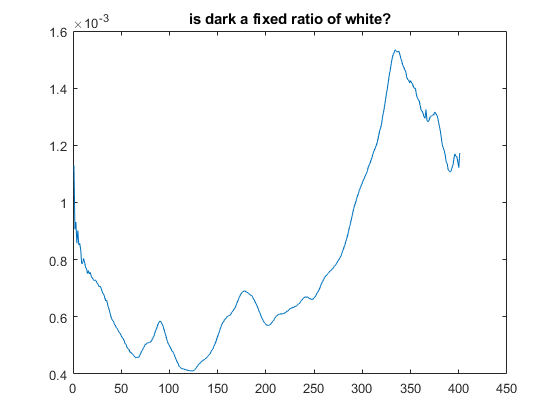


spd_0 = mea_min.amplitude';
spd_max = mea_max.amplitude';

ratio_0 = spd_0 ./ spd_max;

clf
plot(ratio_0)
title('is dark a fixed ratio of white?')

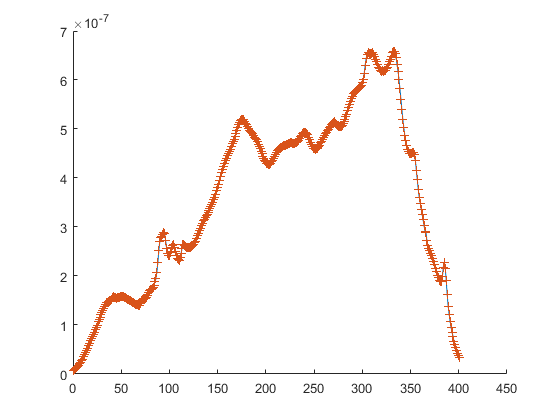


clf
hold on
plot(spd_0)
plot(spd_max .*  ratio_0,'+')


sc = 0.25

sc = 0.2500

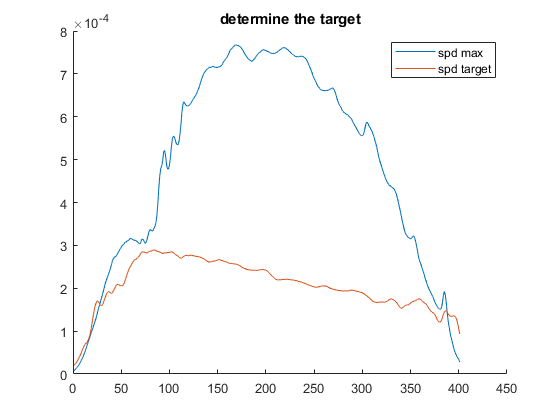

spd_target = spd_target_orig .* sc;
clf
hold on
plot(spd_max)
plot(spd_target)
legend('spd max','spd target')
title('determine the target')

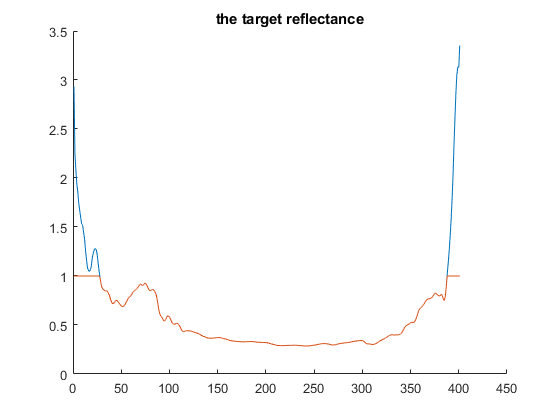

ref_target_orig = (spd_target - spd_0) ./ (spd_max - spd_0);
ref_target = min(1,ref_target_orig);
ref_target()

clf
hold on
plot(ref_target_orig)
plot(ref_target)
title('the target reflectance')

ref_m = ls.col_spec';

vec_a_orig = R_callRsolver1024(ref_m,ref_target);

ans = 'Solving M * A = B with R...'

ans = 0

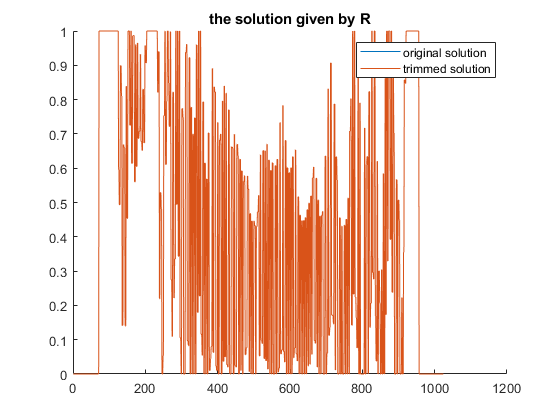

vec_a = vec_a_orig;
vec_a = min(1,vec_a);
vec_a = max(0,vec_a);

clf
hold on
plot(vec_a_orig)
plot(vec_a)
legend('original solution','trimmed solution')
title('the solution given by R')

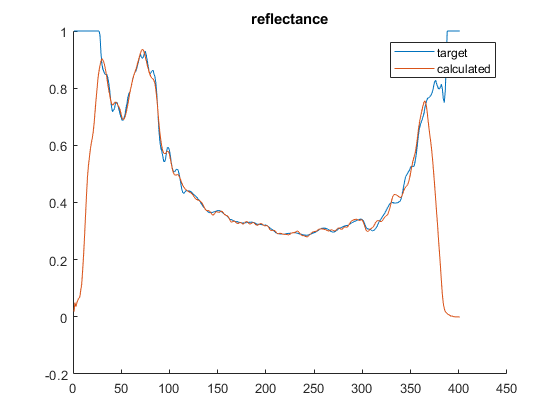

clf
hold on
plot(ref_target)
ref = ref_m * vec_a;
plot(ref)
legend('target','calculated')
title('reflectance')

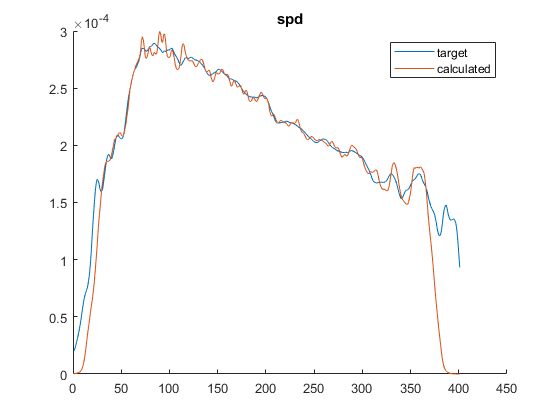

clf
hold on
plot(spd_target)
spd = spd_max .* ref + spd_0;
plot(spd)
legend('target','calculated')
title('spd')


ol.setColumn1024Gamma(vec_a)
mea = cs.measure;

Yxy =    17.5150    0.3115    0.3316


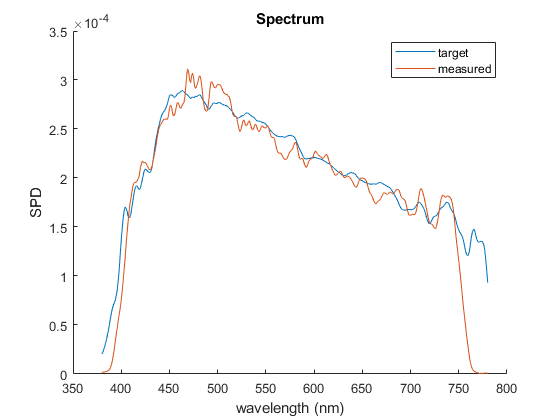


clf
hold on

plot(380:780,spd_target)

mea.plot

legend('target','measured')

clf
hold on
m = measure_white(ol,cs);

Yxy =    52.4180    0.3789    0.4095


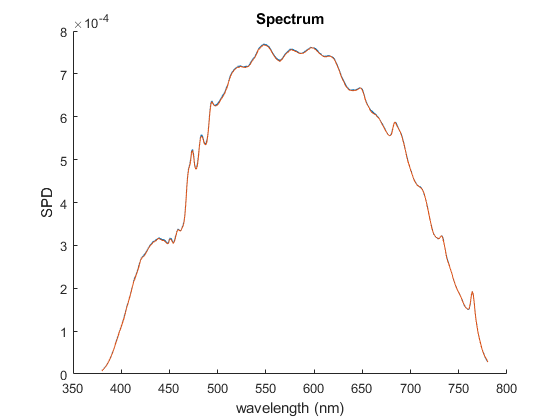

m.plot
plot(380:780,spd_max)

%clf
%plot(t,)

ol.setColumn1024(LightSim.multiple_peaks(1:1024))
mea_all = cs.measure;
clf
mea_all.plot

clf
hold on
plot(380:780,spd_max .* ref_target)
mea.plot
plot(380:780,spd_target)
%plot(380:780,spd_max)
%mea_all.plot

c_range = [1:100:1000];

ol.setColumn1024(LightSim.multiple_peaks(c_range))
mea_500 = cs.measure;

ol.setColumn1024(LightSim.multiple_peaks([1:1024]))
mea_all = cs.measure;

s_pred = ls.predict_by_filter(LightSim.multiple_peaks(c_range));

clf
hold on
t_500 = mea_500.amplitude ./ mea_all.amplitude;
%plot(t_500)
mea_500.plot
plot(380:780,s_pred)

col_g = 435
col_width = 140;
c_range = [col_g-col_width:col_g+col_width];
x_g = 0.33;
y_g = 0.6;
[100 x_g y_g atan2d(y_g,x_g) (x_g.^2+y_g.^2).^0.5]

ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy

col_r = 730
col_width = 150;
c_range = [col_r-col_width:col_r+col_width];
x_r = 0.64;
y_r = 0.30;
[100 x_r y_r atan2d(y_r,x_r) (x_r.^2+y_r.^2).^0.5]

ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy
return

clf
hold on
mea_500.plot

how wide need to reach max

c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea_max = cs.measure;


width = 25;
wl = 708;
c_range = [wl-width:wl+width];
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
clf
hold on
mea_max.plot
mea.plot

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea_8 = cs.measure;

Yxy =    21.0410    0.3850    0.4094


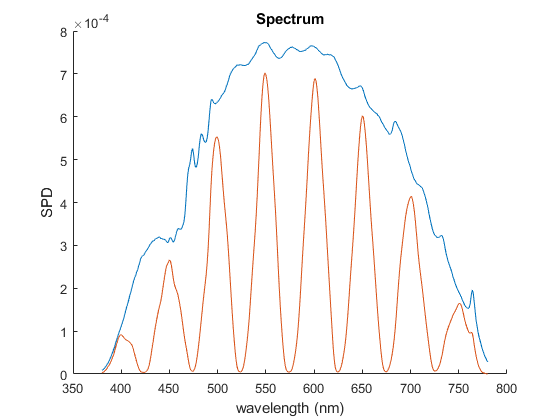


clf
hold on
mea_max.plot
mea_8.plot

i=5;
ol.setColumn1024(vec8_array(i,:))
mea = cs.measure;

Yxy =     6.5854    0.6217    0.3768


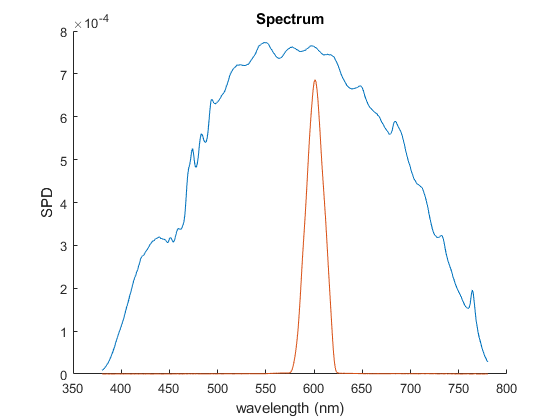

clf
hold on
mea_max.plot
mea.plot

spd_target
index_8 = wl_center - 380 + 1;
amp_8_target = spd_target(index_8)';
amp_8_max = mea_8.amplitude(index_8);
ratio_8 = amp_8_target ./ amp_8_max;
ratiovec_8 = interp1(veclut(:,2),veclut(:,1),ratio_8,'spline')
%ratio_8 = [1 1 1 1 1 1 1 1] * 0.8;

clf
plot(ratio_8)

vec = vec8_array' * ratio_8';
ol.setColumn1024(vec)
mea = cs.measure;
clf
plot(vec)

clf
hold on
mea_max.plot
mea.plot
plot(380:780,spd_target)

for i = 1:10
    ratio_8 = [1 1 1 1 1 1 1 1] * i / 10;
    vec = vec8_array' * ratio_8';
    ol.setColumn1024(vec)
    mea = cs.measure;
    meascale{i} = mea;
end

Yxy =     0.0465    0.3922    0.4068


Yxy =     0.0904    0.3769    0.4005


Yxy =     0.2364    0.3833    0.4043


Yxy =     0.5120    0.3709    0.4000


Yxy =     1.4675    0.3825    0.4098


Yxy =     3.1227    0.3783    0.4078


Yxy =     5.9274    0.3804    0.4087


Yxy =    10.1220    0.3833    0.4099


Yxy =    15.1560    0.3845    0.4100


Yxy =    20.9050    0.3851    0.4094


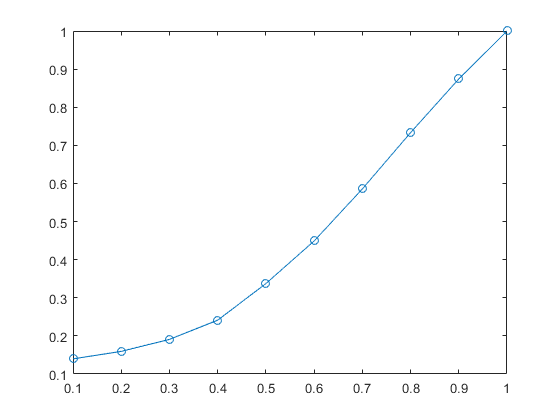


r = zeros(8,401);
for i = 1:10
    r(i,:) = meascale{i}.amplitude ./ meascale{10}.amplitude;
end
rmean = mean(r,2);
%veclut = [[0.1:0.1:1]' rmean]
%save('veclut','veclut')
clf
plot(0.1:0.1:1,rmean.^(1/2.2),'o-')

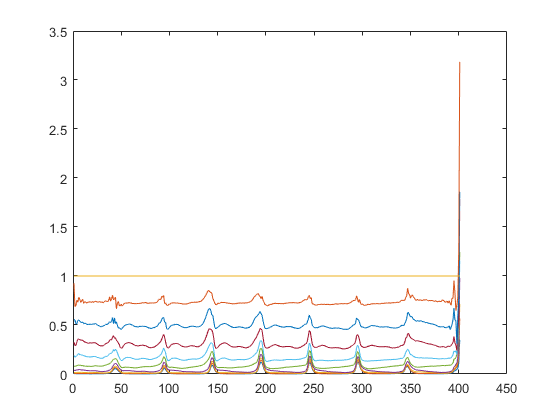



clf
plot(r')

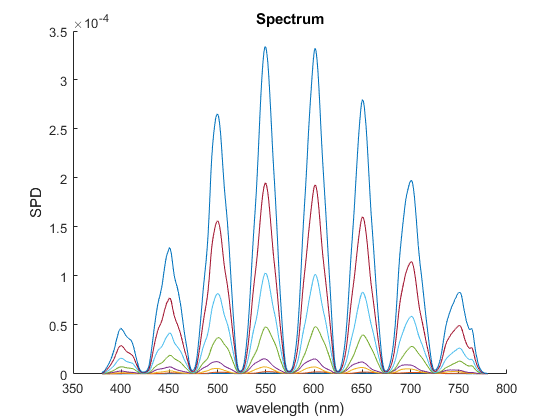


clf
hold on
for i = 1:8
    meascale{i}.plot
end

ratio_spec = zeros(10,401);
col_range  = [1:1024];
for i = 1:10
    rat = i/10;
    vec = LightSim.multiple_peaks(col_range) * rat;
    ol.setColumn1024(vec)
    mea = cs.measure;
    ratio_spec(i,:) = mea.amplitude;
end

Yxy =     0.0688    0.3802    0.4008


Yxy =     0.1798    0.3621    0.3943


Yxy =     0.5451    0.3716    0.4012


Yxy =     1.2330    0.3592    0.3965


Yxy =     3.6238    0.3728    0.4053


Yxy =     7.7674    0.3700    0.4049


Yxy =    14.7750    0.3730    0.4072


Yxy =    25.1260    0.3764    0.4091


Yxy =    38.1310    0.3779    0.4095


Yxy =    52.6920    0.3789    0.4097


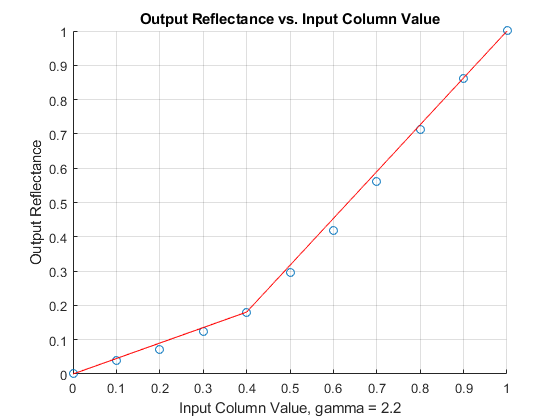

ratio_max = repmat(ratio_spec(10,:),10,1);
ratio_min = repmat(mea_min.amplitude,10,1);
ratio_spec_normal = (ratio_spec - ratio_min) ./ (ratio_max - ratio_min);
ratio_spec_normal_mean = mean(ratio_spec_normal(:,50:end-50)');

gamma_lut = [[0:0.1:1]' [0 ratio_spec_normal_mean]'];
save('gamma_lut','gamma_lut')

clf
hold on
x = gamma_lut(:,1);
y = gamma_lut(:,2);
plot(x,y.^(1/2.2),'o')
knee = 5;
plot(x([1 knee]),y([1 knee]).^(1/2.2),'-r')
plot(x([knee 11]),y([knee 11]).^(1/2.2),'-r')
grid on
axis([0 1 0 1])
xlabel('Input Column Value, gamma = 2.2')
ylabel('Output Reflectance')
title('Output Reflectance vs. Input Column Value')



clf
plot(ratio_spec_normal(:,:)')

clf
hold on
x = 0.1:0.1:1;
y = mean(ratio_spec_normal(:,50:end-50)');
plot(x,y.^(1/2.2),'o')
%axis([0 1 0 1])
plot(x([1 4]),y([1 4]).^(1/2.2),'-r')
plot(x([4 10]),y([4 10]).^(1/2.2),'-r')
grid on

clf
semilogy(x,y)
grid on

slope = mean((y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1)))
perc = y ./ x


ratio_spec_normal = ratio_spec ./ repmat(ratio_spec(10,:),10,1);

clf
plot(ratio_spec_normal(:,:)')

clf
hold on
x = 0.1:0.1:1;
y = mean(ratio_spec_normal(:,50:end-50)');
plot(x,y.^(1/2.2),'o')
%axis([0 1 0 1])
plot(x([1 4]),y([1 4]).^(1/2.2),'-r')
plot(x([4 10]),y([4 10]).^(1/2.2),'-r')
grid on

clf
semilogy(x,y)
grid on

slope = mean((y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1)))
perc = y ./ x


Stability test


col_range  = [1:1024];
k = 500;
col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

clf
hold on
for i = 1:10
    ol.setColumn1024(vec)
    mea = cs.measure;
    mea.plot
    spec_stable(i,:) = mea.amplitude';
end

Try subtractive method


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;
spec_measured0 = mea.amplitude';
lum = sum(spec_measured)

k = 400
col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;
spec_measured1 = mea.amplitude';
ref_diff = (spec_measured0 - spec_measured1) ./ spec_measured0;

ref1 = spec_measured1 ./ spec_measured0;

%spec_predicted = ls.predict_vec_max(vec,spec_max);

%ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
%plot(380:780,spec_measured0)
plot(380:780,ref_diff)
plot(380:780,ls.reflectance(k,:))
%plot(380:780,spec_measured0)
%plot(380:780,spec_measured1)
%plot(380:780,spec_predicted)
%legend('measured','predicted')

Check control accuracy


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024Gamma(vec)
mea = cs.measure;
spec_measured = mea.amplitude';
lum = sum(spec_measured)

spec_predicted = ls.predict_vec_max(vec,spd_max);

ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
plot(380:780,spec_measured)
plot(380:780,spec_predicted)
legend('measured','predicted')


light intensity changes over time -- full

spec_predicted = ls.predict_vec_max(LightSim.multiple_peaks([1:1024]),spd_max);

mea = measure_white(ol,cs);
spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all,':')
legend('predicted','measured','adjusted')


Q: why prediction inaccurate?

A: compare prediction and measurement with 8 spikes

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

spec_predicted = ls.predict_vec_max(vec8_sum',spd_max);

ol.setColumn1024(vec8_sum)
mea = cs.measure;
spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all)
legend('predicted','measured','adjusted')

C: there is spectral shifting -- use max(spec) to get amplitude

vec8_array = ls.vec_8_pencils;
vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea = cs.measure;
spec_measured = mea.amplitude';

clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
legend('predicted','measured')
plot(380:780,spd_max)


peaks = ls.find_spikes(ls.vec_8_wl,spec_measured);
spike_measured = peaks(:,2);
spike_max = spd_max(peaks(:,1)-380+1);
spike_measured ./ spike_max
plot(ls.vec_8_wl,spike_measured,'o')
plot(ls.vec_8_wl,spike_max,'o')

spike_white = {};
spike_spike = {};
for i = 1:50
    spike_white{i} = measure_white(ol,cs);
    
    wl_range = [400+(i-1)*1:50:750];
    mea = measure_8_spikes(ol,cs,wl_range);
    spike_spike{i} = mea; 
end
spike_black = measure_black(ol,cs);

save('spike_0531.mat','spike_black','spike_white','spike_spike')

clf
hold on
for i = 1:50
   spike_white{i}.plot
end

rr = zeros(750,1);
for i = 1:50
   spike_ratio{i} = spike_spike{i}.amplitude ./ spike_white{i}.amplitude;
   rr(400+(i-1)*1:50:750) = spike_ratio{i};
end
rrr = rr(400:1:750);
clf
plot(rrr)

clf
i = 6
plot(ls.ref{i})


% 6/2/2022
%
% collect data
%
spike_white = {};
spike_spike = {};
for i = 1:50
    spike_white{i} = measure_white(ol,cs);
    
    wl_range = [400+(i-1)*1:50:750];
    mea = measure_8_spikes(ol,cs,wl_range);
    spike_spike{i} = mea; 
end

spike_black = measure_black(ol,cs);
save('spike_0602.mat','spike_black','spike_white','spike_spike')

clf
hold on
for i = 1:50
    spike_spike{i}.plot;
end

%
% calculate the reflectance
%
spike_reflectance = zeros(50,401);
for i = 1:50
    spike_reflectance(i,:) = (spike_spike{i}.amplitude-spike_black.amplitude)./(spike_white{i}.amplitude - spike_black.amplitude);
end

%
% visualize
%
clf
i = 17;
plot(380:780,spike_reflectance(i,:));
axis([350 800 0 0.03])

%
% break the combs
%

comb_array = zeros(750,780);

for i = 1:50
    % decide the x values
    wl_range = [400+(i-1)*1:50:750];
    wl_range_n = length(wl_range);
    
    % take one curve
    comb = spike_reflectance(i,:);
    
    % convert to real wavelength
    comb_real = zeros(1,780);
    comb_real(1,380:780) = comb;
    
    % iterate each spike
    for j = 1:wl_range_n
        wl = wl_range(j);
        wl_width = 25;
        
        comb_array(wl,wl-wl_width:wl+wl_width) = comb_real(1,wl-wl_width:wl+wl_width);
    end
    
end

%
% visualize
%
clf
i = 648;
plot(comb_array(i,:))
axis([380 780 0 0.03])

% 6/3/2022
%
% link column with spectrum
%
col_spec = zeros(1024,401);

% mapping between column and wavelength from previous findings 
col_center = [72 202 327 454 583 708 834 956];
wl_center = [400 450 500 550 600 650 700 750];

% interpolate columns between 72 and 956
for col_i = 72:956
    wl_i = round(interp1(col_center,wl_center,col_i,'linear'));
    spec = comb_array(wl_i,:);
    col_spec(col_i,:) = spec(380:780);
end
            

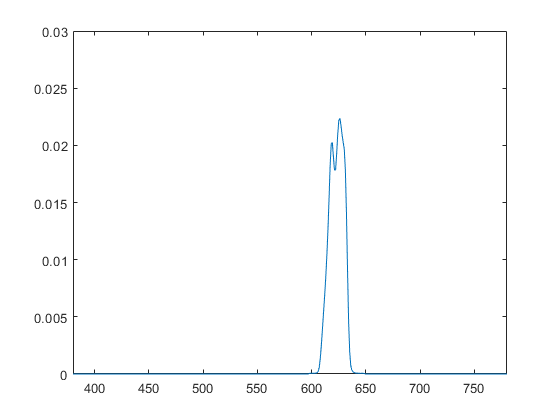

%
% visualize
%
clf
i = 640;
plot(380:780,col_spec(i,:))
axis([380 780 0 0.03])

save('col_spec.mat','col_spec')

Check control accuracy


col_range  = [100:100:1024];

vec = LightSim.multiple_peaks(col_range)*0.9;

ol.setColumn1024Gamma(vec)
mea = cs.measure;

Yxy =     0.5051    0.3846    0.4160


spec_measured = mea.amplitude';
lum = sum(spec_measured)

lum = 0.0019

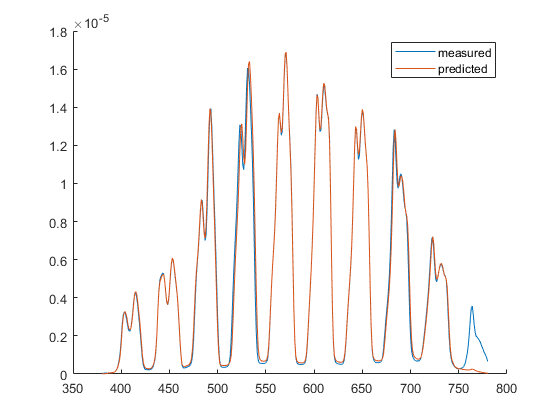


spec_predicted = ls.predict_col_spec(vec,spd_max);

% ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
plot(380:780,spec_measured)
plot(380:780,spec_predicted)
legend('measured','predicted')

function mea = measure_white (ol,cs)
c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
end

function mea = measure_black (ol,cs)
c_range = [];
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
end

function mea = measure_8_spikes (ol,cs,wl_range)
load('column_transparency.mat','col_wl')
col_range = round(interp1(col_wl(:,2),col_wl(:,1),wl_range,'spline','extrap'));
col_range = min(col_range,1024);
col_range = max(col_range,1);
vec = LightSim.multiple_peaks(col_range);
ol.setColumn1024(vec)
mea = cs.measure;
end